# Likelihood vs CSB: pendulum example

clear;clc
syms x_1(t) x_2(t) m f g l u(t) %symbolic state variables and parameters
u(t)=1;
%Defining the system of differential equations
ode1 = diff(x_1) == x_2;
ode2 = diff(x_2) == -f*x_2/m - g*sin(x_1)/l + u(t)/(m*l);
%Array with the system
odes=[ode1; ode2]

$$odes(t) = \left(\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=\frac{1}{l\,m}-\frac{f\,x_{2}\left(t\right)}{m}-\frac{g\,\sin\left(x_{1}\left(t\right)\right)}{l} \end{array}\right)$$

%choose an order for state variables
vars = [x_1 x_2];
domain=[0 100];%rango numérico en el que se solucionará el sistema
modelName='pend';%nombre para el archivo de modelo
gsua_dataprep(odes,vars,domain,modelName);%consultamos el orden para introducir los parámetros

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccc} x_{1}\left(t\right) & x_{2}\left(t\right) & f & g & l & m \end{array}\right)$$

Ranges=[-1 1;-1 1;0 1; 9.5 10.5; 2 4; 3 7];%generamos rangos para dicho orden
T = gsua_dataprep(odes,vars,domain,modelName,'range',Ranges)%generamos la tabla del sistema

Setting environment to work with symbolic Matlab
Introduce ranges in the following order: 


$$ans = \left(\begin{array}{cccccc} x_{1}\left(t\right) & x_{2}\left(t\right) & f & g & l & m \end{array}\right)$$

T = 6×2 table
               Range       Nominal
            ___________    _______

    x_10     -1       1        0  
    x_20     -1       1        0  
    f         0       1      0.5  
    g       9.5    10.5       10  
    l         2       4        3  
    m         3       7        5  


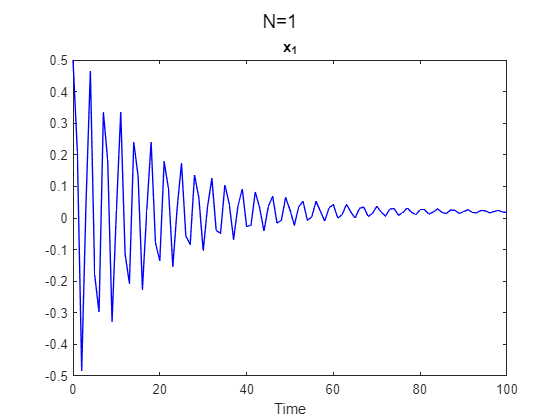

T.Properties.CustomProperties.output=1;
T.Nominal=[0.5 0.5 0.5 9.8 3 5]';
xdata=0:1:100;
gsua_eval(T.Nominal,T,xdata);

Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 1

Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
<a href = "m

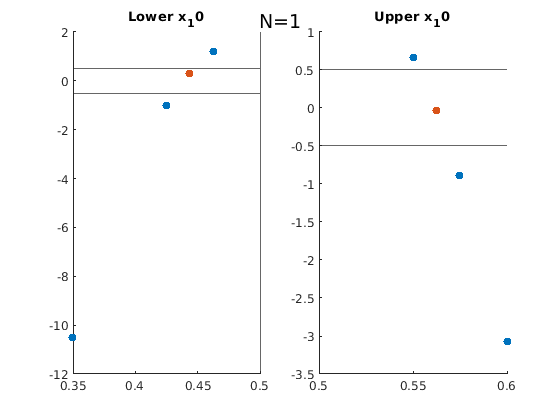

Progress: 17%
Estimated processing time (h:m:s): 0:2:51
Remaining time (h:m:s): 0:2:22
Elapsed time (h:m:s): 0:0:28
Estimated stop time (h:m:s): 11:10:46
Number of simulations: 12
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 1

<a href = "ma

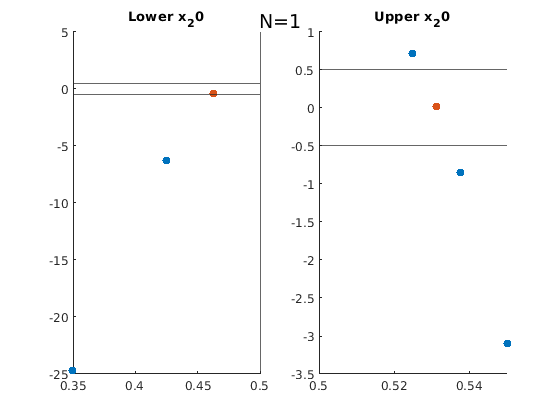

Progress: 34%
Estimated processing time (h:m:s): 0:1:57
Remaining time (h:m:s): 0:1:18
Elapsed time (h:m:s): 0:0:39
Estimated stop time (h:m:s): 11:9:52
Number of simulations: 12
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 1

<a href = "mat

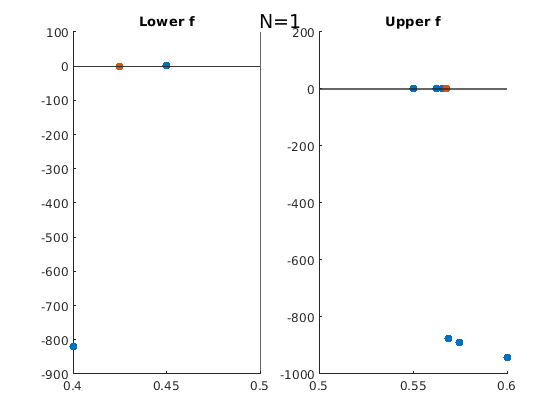

Progress: 50%
Estimated processing time (h:m:s): 0:2:26
Remaining time (h:m:s): 0:1:13
Elapsed time (h:m:s): 0:1:13
Estimated stop time (h:m:s): 11:10:21
Number of simulations: 12
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 1

<a href = "ma

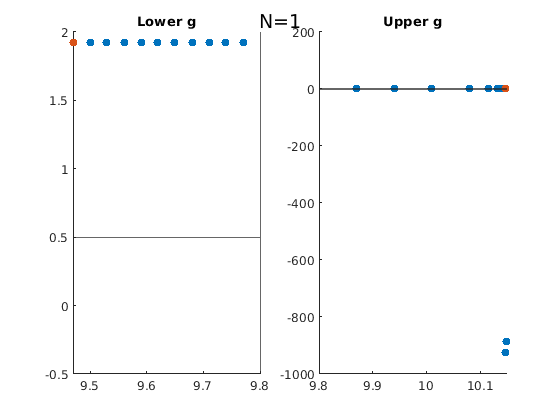

Progress: 67%
Estimated processing time (h:m:s): 0:4:6
Remaining time (h:m:s): 0:1:22
Elapsed time (h:m:s): 0:2:44
Estimated stop time (h:m:s): 11:12:1
Number of simulations: 12
Estimation 1

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria

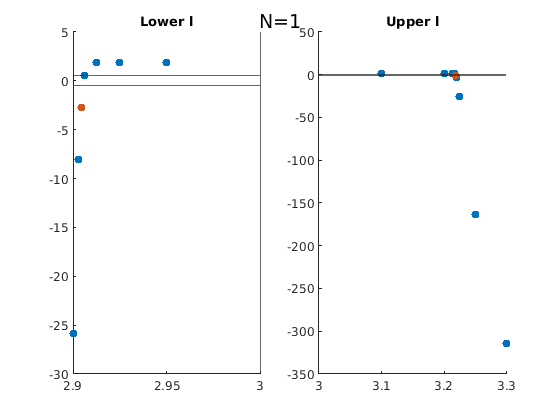

Progress: 84%
Estimated processing time (h:m:s): 0:4:44
Remaining time (h:m:s): 0:0:47
Elapsed time (h:m:s): 0:3:57
Estimated stop time (h:m:s): 11:12:39
Number of simulations: 12
Estimation 1

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Estimation 1

<a href = "ma

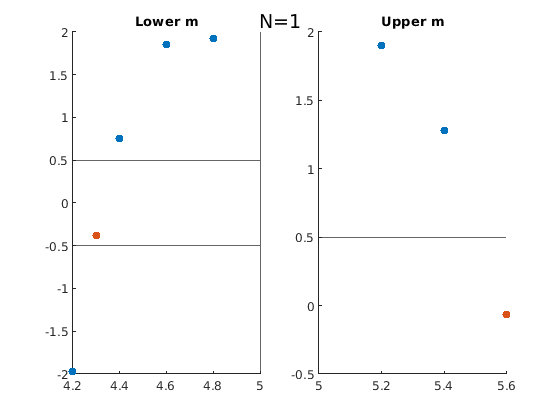

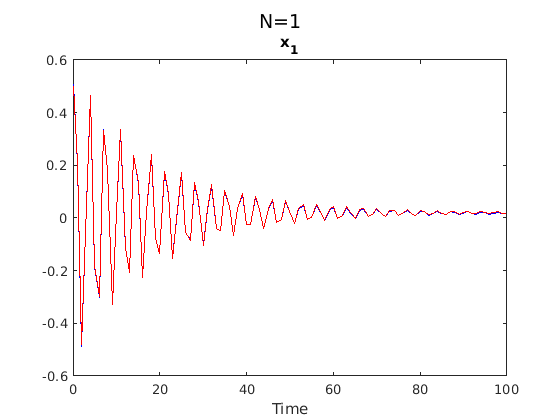

Progress: 100%
Estimated processing time (h:m:s): 0:4:33
Remaining time (h:m:s): 0:0:0
Elapsed time (h:m:s): 0:4:33
Estimated stop time (h:m:s): 11:12:28
Number of simulations: 12


Tia=gsua_likelihood(T,xdata,[],0.95,0.1,1.3,0.5,0.001,100,1,true,false,true,[]);

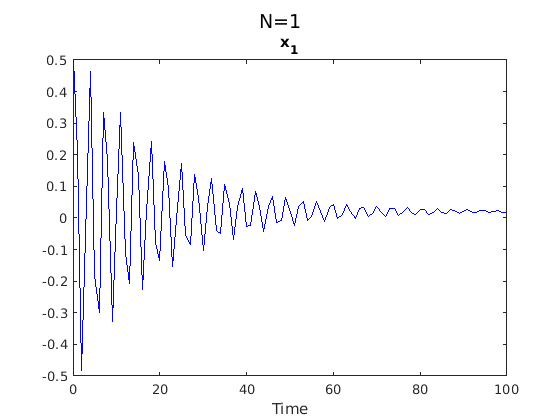

Mia=gsua_dmatrix(Tia,500);
ydata=gsua_eval(T.Nominal,T);

%gsua_ua(Mia,Tia,'parallel',false,'ynom',ydata);

Sim500 Done
Sim499 Done
Sim498 Done
Sim497 Done
Sim496 Done
Sim495 Done
Sim494 Done
Sim493 Done
Sim492 Done
Sim491 Done
Sim490 Done
Sim489 Done
Sim488 Done
Sim487 Done
Sim486 Done
Sim485 Done
Sim484 Done
Sim483 Done
Sim482 Done
Sim481 Done
Sim480 Done
Sim479 Done
Sim478 Done
Sim477 Done
Sim476 Done
Sim475 Done
Sim474 Done
Sim473 Done
Sim472 Done
Sim471 Done
Sim470 Done
Sim469 Done
Sim468 Done
Sim467 Done
Sim466 Done
Sim465 Done
Sim464 Done
Sim463 Done
Sim462 Done
Sim461 Done
Sim460 Done
Sim459 Done
Sim458 Done
Sim457 Done
Sim456 Done
Sim455 Done
Sim454 Done
Sim453 Done
Sim452 Done
Sim451 Done
Sim450 Done
Sim449 Done
Sim448 Done
Sim447 Done
Sim446 Done
Sim445 Done
Sim444 Done
Sim443 Done
Sim442 Done
Sim441 Done
Sim440 Done
Sim439 Done
Sim438 Done
Sim437 Done
Sim436 Done
Sim435 Done
Sim434 Done
Sim433 Done
Sim432 Done
Sim431 Done
Sim430 Done
Sim429 Done
Sim428 Done
Sim427 Done
Sim426 Done
Sim425 Done
Sim424 Done
Sim423 Done
Sim422 Done
Sim421 Done
Sim420 Done
Sim419 Done
Sim418 Done
Sim4

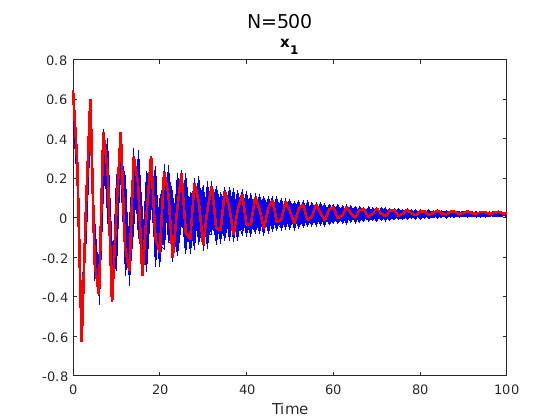

ydata2=ydata*1.3;
yia=gsua_eval(Mia',Tia,0:100,ydata2);

Toat=gsua_oatr(T)

Expansion-reduction Method OAT is being launched
------------------------------------
Calculus of m Starting
Range for m Done!
Initial range of m(6)--> 3  7
Actual range --> 3.1344         7.4
Calculus of l Starting
Range for l Done!
Initial range of l(5)--> 2  4
Actual range --> 2.9266      3.0766
Calculus of g Starting
Range for g Done!
Initial range of g(4)--> 9.5         10.5
Actual range --> 9.55813      10.0445
Calculus of f Starting
Range for f Done!
Initial range of f(3)--> 0  1
Actual range --> 0.33242     0.83281
Calculus of x_20 Starting
Range for x_20 Done!
Initial range of x_20(2)--> -1  1
Actual range --> 0.22812     0.75195
Calculus of x_10 Starting
Range for x_10 Done!
Initial range of x_10(1)--> -1  1
Actual range --> 0.3125     0.68164


Toat = 6×2 table
                  Range           Nominal
            __________________    _______
    x_10     0.3125    0.68164      0.5  
    x_20    0.22812    0.75195      0.5  
    f       0.33242    0.83281      0.5  
    g        9.5581     10.044      9.8  
    l        2.9266     3.0766        3  
    m        3.1344        7.4        5  

Tcsb=gsua_csb(Toat,5e3,'protect',true);

------------------------------------
Ranges calculation is being launched
------------------------------------
Progress: 1%
Estimated processing time (h:m:s): 0:31:49
Remaining time (h:m:s): 0:31:30
Elapsed time (h:m:s): 0:0:19
Estimated stop time (h:m:s): 11:44:25
Number of simulations: 500000
------------------------------------
1539 Scalars have been detected in the especified range
------------------------------------
12--> Reductions done in this iteration
------------------------------
    "Running method "    "1"
------------------------------
Progress: 2%
Estimated processing time (h:m:s): 0:34:23
Remaining time (h:m:s): 0:33:41
Elapsed time (h:m:s): 0:0:41
Estimated stop time (h:m:s): 11:46:59
Number of simulations: 500000
------------------------------------
2920 Scalars have been detected in the especified range
------------------------------------
12--> Reductions done in this iteration
------------------------------
    "Running method "    "1"
----------------------------

Sim500 Done
Sim499 Done
Sim498 Done
Sim497 Done
Sim496 Done
Sim495 Done
Sim494 Done
Sim493 Done
Sim492 Done
Sim491 Done
Sim490 Done
Sim489 Done
Sim488 Done
Sim487 Done
Sim486 Done
Sim485 Done
Sim484 Done
Sim483 Done
Sim482 Done
Sim481 Done
Sim480 Done
Sim479 Done
Sim478 Done
Sim477 Done
Sim476 Done
Sim475 Done
Sim474 Done
Sim473 Done
Sim472 Done
Sim471 Done
Sim470 Done
Sim469 Done
Sim468 Done
Sim467 Done
Sim466 Done
Sim465 Done
Sim464 Done
Sim463 Done
Sim462 Done
Sim461 Done
Sim460 Done
Sim459 Done
Sim458 Done
Sim457 Done
Sim456 Done
Sim455 Done
Sim454 Done
Sim453 Done
Sim452 Done
Sim451 Done
Sim450 Done
Sim449 Done
Sim448 Done
Sim447 Done
Sim446 Done
Sim445 Done
Sim444 Done
Sim443 Done
Sim442 Done
Sim441 Done
Sim440 Done
Sim439 Done
Sim438 Done
Sim437 Done
Sim436 Done
Sim435 Done
Sim434 Done
Sim433 Done
Sim432 Done
Sim431 Done
Sim430 Done
Sim429 Done
Sim428 Done
Sim427 Done
Sim426 Done
Sim425 Done
Sim424 Done
Sim423 Done
Sim422 Done
Sim421 Done
Sim420 Done
Sim419 Done
Sim418 Done
Sim4

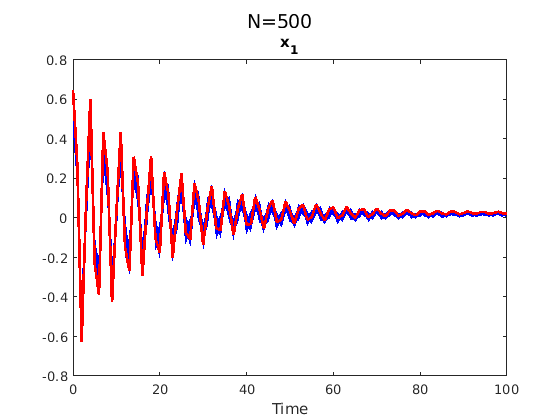

Mcsb=gsua_dmatrix(Tcsb,500);
ycsb=gsua_eval(Mcsb',T,xdata,ydata2);

Jia = gsua_costfMulti(yia,ydata,0.3,false);
Jcsb = gsua_costfMulti(ycsb,ydata,0.3,false);
Jtest=gsua_costfMulti(ydata2,ydata,0.3,false)

Jtest = 1

[Jia2,orderia]=sort(Jia);
[Jcsb2,ordercsb]=sort(Jcsb);
supia=find(Jia2 < 1, 1, 'last' ); 
supcsb=find(Jcsb2 < 1, 1, 'last' ); 

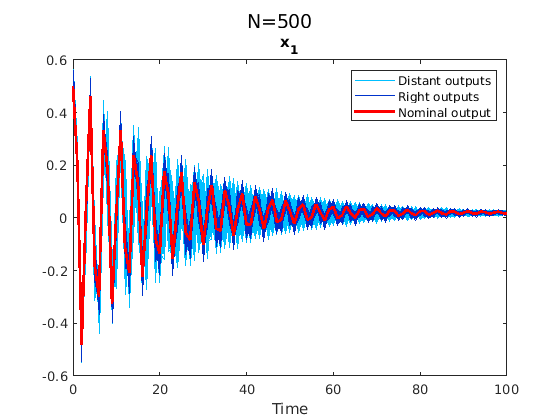

gsua_plot('UncertaintyAnalysis',T,yia(orderia,:,:),xdata,ydata,supia);

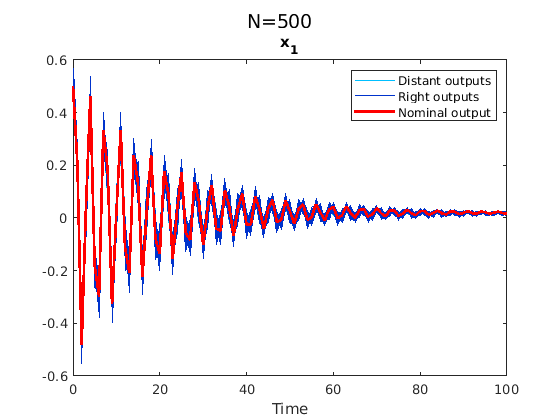

gsua_plot('UncertaintyAnalysis',T,ycsb(ordercsb,:,:),xdata,ydata,supcsb);

%Tcsb2=gsua_csb(Toat,5e3,'protect',true,'margin',);
Tcsb

Tcsb = 6×2 table
                  Range           Nominal
            __________________    _______
    x_10    0.42556    0.56858      0.5  
    x_20    0.38857    0.59151      0.5  
    f       0.48569    0.67955      0.5  
    g         9.685     9.9176      9.8  
    l        2.9693     3.0338        3  
    m        4.5979     5.9365        5  

Tia

Tia = 6×2 table
                  Range           Nominal
            __________________    _______
    x_10    0.44375     0.5625      0.5  
    x_20     0.4625    0.53125      0.5  
    f         0.425    0.56797      0.5  
    g           9.5     10.147      9.8  
    l        2.9047     3.2172        3  
    m           4.3        5.6        5  

ydata2=ydata+ydata.*normrnd(0,0.001,1,101);
[x,resnorm,residual,exitflag,output,lambda,jacobian] = lsqcurvefit(@(pars,xaxis) gsua_deval(pars,T,xaxis),T.Nominal',xdata,ydata2,T.Range(:,1),T.Range(:,2));


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


ci = nlparci(x,residual,'jacobian',jacobian)

ci =     0.4999    0.5002
    0.4997    0.5002
  -34.0106   35.0113
 -666.1561  685.7564
 -203.9254  209.9255
 -339.9372  349.9391


t2=table(x(:));
t2.Nominal=T.Nominal;
t2.Ci=ci

t2 = 6×3 table
     Var1      Nominal            Ci        
    _______    _______    __________________

    0.50007      0.5      0.49991    0.50023
    0.49995      0.5      0.49971    0.50019
    0.50034      0.5      -34.011     35.011
     9.8001      9.8      -666.16     685.76
          3        3      -203.93     209.93
      5.001        5      -339.94     349.94
